# TCLab FOPDT Regression

**Objective**: Collect step response data from the TCLab and compute parameters of an FOPDT model using an optimization method.

A single step response is required for a graphical fit of FOPDT Parameters, as discussed in Lesson 6. A regression or optimization method can be used when the data cannot be fit with a graphical method. A First Order Plus Dead Time (FOPDT) model of the Temperature Control Lab (TCLab) is the following:


$$\tau_p \frac{dT'}{dt} = -T' + K_p \, Q'\left(t-\theta_p\right)$$


where $T'=T-T_{ss}$ and $Q'=Q-Q_{ss}$ are deviation variables with steady-state initial conditions $T_{ss}=23^\circ\text{C}$ and $Q_{ss}=0\%$. Perform multiple step tests with heater 1 starting at 0% for 0.5 minutes (30 seconds) and then step the heater to values between 10% and 70% for 13.5 minutes in 3-5 minute intervals. Create a plot of the temperature response over 14 minutes that shows the temperature ($^\circ \text{C}$) and heater level (%). Use the sample source code below for generating a plot (*Step_Response.png*) and data file (*Step_Response.csv*).

viewSolution(true)

clc; clear all; close all;
tmp = matlab.desktop.editor.getActive;
directory = fileparts(tmp.Filename);


n = 14 * 60;  % number of seconds to test
time = linspace(0, n, n+1);

% Collect data
filename = 'Step_Response.csv';
absolute_path = fullfile(directory, filename);

% Arrays for Time and Temperature
T1 = zeros(n+1, 1);
tm = zeros(n+1, 1);
% CREATE INTERVALS FOR THE HEATER TO CHANGE
Q1 = zeros(n+1, 1);
Q1(31:4*60) = 70;
Q1(4*60+1:9*60) = 20;
Q1(8*60+1:end) = 45;

try % try to read from file first
    A = readmatrix(absolute_path)
    tm = A(:,1);
    T1 = A(:,2);
    disp('TCLab Data read from file')
    
catch % if file can not be found, simulate
    try 
        % initialize lab
        lab = tclab;
        tic;
        for i=1:n+1
            tm(i) = toc;
            T1(i) = lab.T1;
            lab.Q1(Q1(i));
            figure(1)
            subplot(2,1,1)
            plot(tm(1:i), T1(1:i), 'r.')
            ylabel('Temperature (C)')
            subplot(2,1,2)
            plot(t

### Gather Data

clc; clear all; close all;
tmp = matlab.desktop.editor.getActive;
directory = fileparts(tmp.Filename);


n = 14 * 60;  % number of seconds to test
time = linspace(0, n, n+1);

% Collect data
filename = "Step_Response.csv";
absolute_path = fullfile(directory, filename);

Arrays for Time and Temperature

T1 = zeros(n+1, 1);
tm = zeros(n+1, 1);

CREATE INTERVALS FOR THE HEATER TO CHANGE

try % try to read from file first
    A = readmatrix(absolute_path)
    tm = A(:,1);
    T1 = A(:,2);
    disp('TCLab Data read from file')
    
catch % if file can not be found, simulate
    try 
        % initialize lab
        lab = tclab;
        tic;
        for i=1:n+1
            tm(i) = toc;
            T1(i) = lab.T1;
            lab.Q1(Q1(i));
            figure(1)
            subplot(2,1,1)
            plot(tm(1:i), T1(1:i), 'r.')
            ylabel('Temperature (C)')
            subplot(2,1,2)
            plot(tm(1:i), Q1(1:i), 'r.')
            xlabel('Time (sec)')
            ylabel('Heater Setting (%)')
            pause(1-mod(tic-toc,1));
        end
        lab.off;
        clear lab;
        
        % save
        A = [tm T1]
        writematrix(A, absolute_path, 'Delimiter', ',')
        
    catch % if an error, turn off heater and close
        lab.off;
        clear lab;
    end
    
end

### Fit FOPDT To Data

Using one of the methods in *Lesson 7: Optimize Model Parameter Fit*, calculate the values of $K_p$, $\tau_p$, and $\theta_p$. In addition, specify the units of these parameters and compare them to the graphical FOPDT fit performed in *Lesson 6: Graphical Fit for TCLab Dynamics.*

FIT THE PARAMETERS BELOW AND GRAPH THE DATA AND THE FOPDT TO ENSURE A GOOD FIT

CREATE FUNCTIONS BELOW. WHILE THERE ARE A VARIETY OF METHODS, ALL OF THEM REQURE THE FOLLOWING:

1) A FUNCTION THAT MODELS $\frac{dy}{dt}
$ FOR THE FOPDT

2) A FUNCTION THAT SIMULATES THE FOPDT FOR THE COURSE OF THE SIMULATION USING THE HEATER INPUT AND RETURNING THE MODELED TEMPERATURE

3) AN OBJECTIVE FUNCTION TO BE MINIMIZED  

### Solution

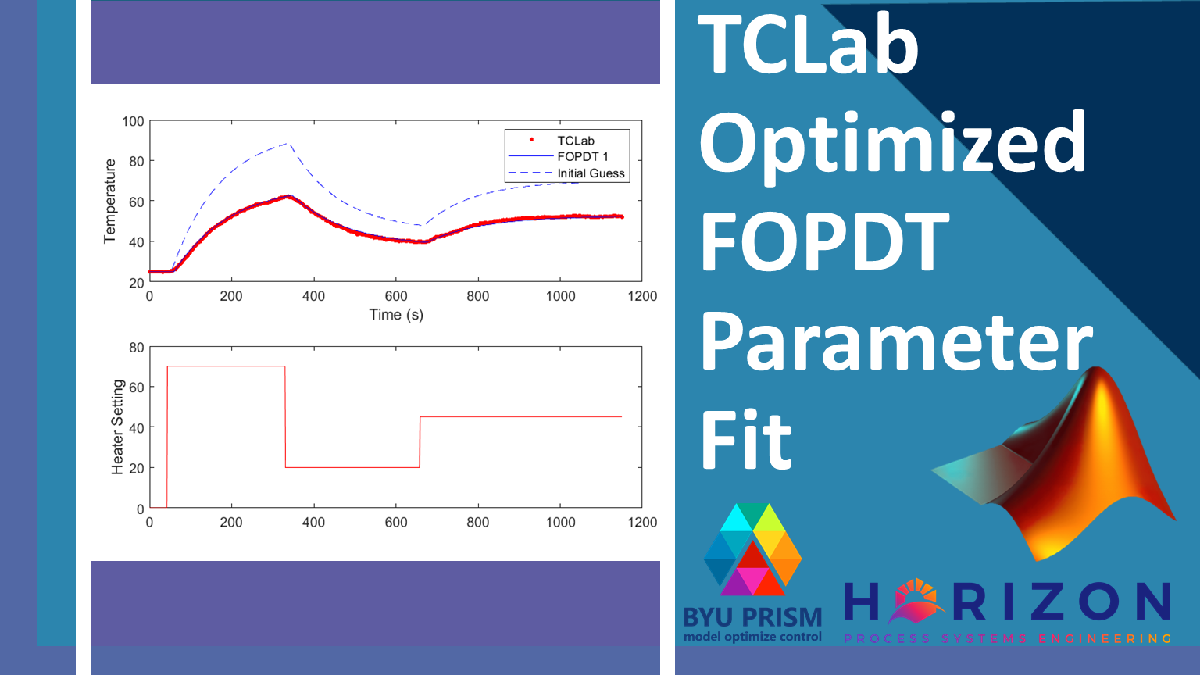

### [View Solution Video](https://youtu.be/CvAIllYe1OU)

function viewSolution(view)
if view
	disp("clc; clear all; close all;" + newline + ...
	     "tmp = matlab.desktop.editor.getActive;" + newline + ...
	     "directory = fileparts(tmp.Filename);" + newline + ...
	     "" + newline + ...
	     "" + newline + ...
	     "n = 14 * 60;  % number of seconds to test" + newline + ...
	     "time = linspace(0, n, n+1);" + newline + ...
	     "" + newline + ...
	     "% Collect data" + newline + ...
	     "filename = 'Step_Response.csv';" + newline + ...
	     "absolute_path = fullfile(directory, filename);" + newline + ...
	     "" + newline + ...
	     "% Arrays for Time and Temperature" + newline + ...
	     "T1 = zeros(n+1, 1);" + newline + ...
	     "tm = zeros(n+1, 1);" + newline + ...
	     "% CREATE INTERVALS FOR THE HEATER TO CHANGE" + newline + ...
	     "Q1 = zeros(n+1, 1);" + newline + ...
	     "Q1(31:4*60) = 70;" + newline + ...
	     "Q1(4*60+1:9*60) = 20;" + newline + ...
	     "Q1(8*60+1:end) = 45;" + newline + ...
	     "" + newline + ...
	     "try % try to read from file first" + newline + ...
	     "    A = readmatrix(absolute_path)" + newline + ...
	     "    tm = A(:,1);" + newline + ...
	     "    T1 = A(:,2);" + newline + ...
	     "    disp('TCLab Data read from file')" + newline + ...
	     "    " + newline + ...
	     "catch % if file can not be found, simulate" + newline + ...
	     "    try " + newline + ...
	     "        % initialize lab" + newline + ...
	     "        lab = tclab;" + newline + ...
	     "        tic;" + newline + ...
	     "        for i=1:n+1" + newline + ...
	     "            tm(i) = toc;" + newline + ...
	     "            T1(i) = lab.T1;" + newline + ...
	     "            lab.Q1(Q1(i));" + newline + ...
	     "            figure(1)" + newline + ...
	     "            subplot(2,1,1)" + newline + ...
	     "            plot(tm(1:i), T1(1:i), 'r.')" + newline + ...
	     "            ylabel('Temperature (C)')" + newline + ...
	     "            subplot(2,1,2)" + newline + ...
	     "            plot(tm(1:i), Q1(1:i), 'r.')" + newline + ...
	     "            xlabel('Time (sec)')" + newline + ...
	     "            ylabel('Heater Setting (%)')" + newline + ...
	     "            pause(1-mod(tic-toc,1));" + newline + ...
	     "        end" + newline + ...
	     "        lab.off;" + newline + ...
	     "        clear lab;" + newline + ...
	     "        " + newline + ...
	     "        % save" + newline + ...
	     "        A = [tm T1]" + newline + ...
	     "        writematrix(A, absolute_path, 'Delimiter', ',')" + newline + ...
	     "        " + newline + ...
	     "    catch % if an error, turn off heater and close" + newline + ...
	     "        lab.off;" + newline + ...
	     "        clear lab;" + newline + ...
	     "    end" + newline + ...
	     "    " + newline + ...
	     "end" + newline + ...
	     "" + newline + ...
	     "% Fit FOPDT To Data" + newline + ...
	     "x0 = zeros(3,1);" + newline + ...
	     "x0(1) = 1; %Km" + newline + ...
	     "x0(2) = 120; %taum" + newline + ...
	     "x0(3) = 10; %thetam" + newline + ...
	     "" + newline + ...
	     "initial_obj = objective(x0, tm, Q1, T1)" + newline + ...
	     "fopdt_params = fminsearch(@(x)objective(x, tm, Q1, T1), x0)" + newline + ...
	     "optimized_obj = objective(fopdt_params, tm, Q1, T1)" + newline + ...
	     "" + newline + ...
	     "y_i = sim_model(x0, tm, Q1, T1);" + newline + ...
	     "y_fopdt = sim_model(fopdt_params,tm, Q1, T1);" + newline + ...
	     "" + newline + ...
	     "figure(2)" + newline + ...
	     "subplot(2,1,1)" + newline + ...
	     "plot(tm, T1, 'r.')" + newline + ...
	     "hold on" + newline + ...
	     "plot(tm, y_fopdt, 'b-')" + newline + ...
	     "plot(tm, y_i, 'b--')" + newline + ...
	     "xlabel('Time (s)')" + newline + ...
	     "hold off" + newline + ...
	     "legend({'TCLab' 'FOPDT 1' 'Initial Guess' })" + newline + ...
	     "ylabel('Temperature')" + newline + ...
	     "subplot(2,1,2)" + newline + ...
	     "plot(tm, Q1, 'r-')" + newline + ...
	     "ylabel('Heater Setting')" + newline + ...
	     "" + newline + ...
	     "% CREATE FUNCTIONS BELOW." + newline + ...
	     "" + newline + ...
	     "function dydt = fopdt(t, y, u, tvals, Km,taum,thetam, yp1, u1)" + newline + ...
	     "    % arguments" + newline + ...
	     "    %  t      = time" + newline + ...
	     "    %  y      = output" + newline + ...
	     "    %  Km     = model gain" + newline + ...
	     "    %  taum   = model time constant" + newline + ...
	     "    %  thetam = model dead time constant" + newline + ...
	     "    %  yp1    = initial output value" + newline + ...
	     "    %  u1     = initial input value" + newline + ...
	     "" + newline + ...
	     "    try" + newline + ...
	     "        if (t-thetam) <= 0" + newline + ...
	     "            um = u1;" + newline + ...
	     "        else" + newline + ...
	     "            um = interp1(tvals, u, t-thetam);" + newline + ...
	     "        end" + newline + ...
	     "    catch " + newline + ...
	     "        disp('Error with time extrapolation: ' + t )" + newline + ...
	     "" + newline + ...
	     "        um = u1;" + newline + ...
	     "    end" + newline + ...
	     "    % calculate derivative" + newline + ...
	     "    dydt = (-(y-yp1) + Km * (um-u1))/taum;" + newline + ...
	     "end" + newline + ...
	     "" + newline + ...
	     "% simulate FOPDT model with x=[Km,taum,thetam]" + newline + ...
	     "function ym = sim_model(x, time_, u_, yp_)" + newline + ...
	     "    % input arguments" + newline + ...
	     "    Km = x(1);" + newline + ...
	     "    taum = x(2);" + newline + ...
	     "    thetam = x(3);" + newline + ...
	     "    " + newline + ...
	     "    ns = length(time_);" + newline + ...
	     "    yp1 = yp_(1);" + newline + ...
	     "    u1 = u_(1);" + newline + ...
	     "    " + newline + ...
	     "    % storage for model values" + newline + ...
	     "    ym = zeros(ns, 1);  % model" + newline + ...
	     "    % initial condition" + newline + ...
	     "    ym(1) = yp1;" + newline + ...
	     "    % loop through time steps    " + newline + ...
	     "    for i = 1:ns-1" + newline + ...
	     "        ts = [time_(i),time_(i+1)];" + newline + ...
	     "        [~, ys] = ode45(@(t, y) fopdt(t, y, u_, time_, Km,taum,thetam, yp1, u1), ts, ym(i));" + newline + ...
	     "        ym(i+1) = ys(end);" + newline + ...
	     "    end" + newline + ...
	     "end" + newline + ...
	     "" + newline + ...
	     "function obj = objective(x_arg, time_, u_, yProcess)" + newline + ...
	     "    % simulate model" + newline + ...
	     "    ym = sim_model(x_arg, time_, u_, yProcess); " + newline + ...
	     "    % calculate objective with sum squared error" + newline + ...
	     "    obj = sum((ym-yProcess).^2)*1000;" + newline + ...
	 "end")
end
end
